# Customize and Extend Simscape Libraries for a Custom DC Motor

Create a custom equation based components for the Simscape Library using the Symbolic Math Toolbox.

## Introduction

The [Symbolic Math Toolbox](https://www.mathworks.com/products/symbolic/) provides a flexible way to develop models from first engineering principles in any spatial dimension. You can develop mathematical models for steady state or transient physics.

You can develop and solve the equations required to represent the physics necessary for your component; and perform your own reduced-order model mapping between the inputs ***x*** and a quantity of interest*** f(x).***

Here ***f*** is the custom component which can represent governing equations in the form of:

- Mathematical formulas 

- Numerical simulations of ODEs and PDEs 

The steps in this examples are 

- Parameterizing a Simscape component using `symReadSSCVariables`

- Define custom equations for your Simscape component using `diff`

- Solve steady-state equations analytically using `solve` and `subs`

- Solve time-dependent equations numerically in MATLAB by using `matlabFunction` and `ode45`

- Create a Simscape component using `symWriteSSC`

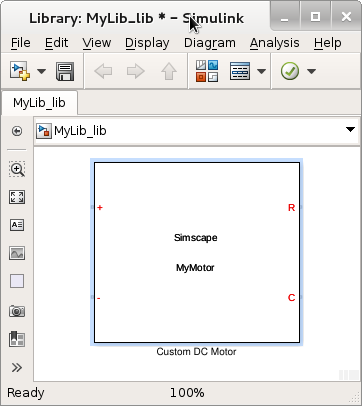

To run this example, you must have licenses for Simscape and Symbolic Math Toolbox.

# DC Motor Model

A DC motor is a device for converting electrical energy into mechanical energy and vice versa. A schematic of a DC motor is shown below (left figure). Blocks that simulate DC motors are provided in [Simscape Electrical](https://www.mathworks.com/help/physmod/sps/index.html)™ (right figure), which is an optional product for [Simscape](https://www.mathworks.com/products/simscape/). 

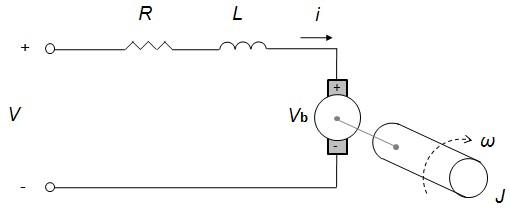    

In this example, we will derive a reduced-order model representation of a DC Motor using the governing Ordinary Differential Equations (ODEs). For a DC motor, the electrical voltage and current is derived from Kirchhoff’s laws and the formula of the mechanical torque is derived from Newton’s laws. Using these equations we can implement a custom and parametric Simscape component.

 
$$\left(\begin{array}{c}
J\,\frac{\partial }{\partial t}\mathrm{\ }w\left(t\right)=\textrm{Ki}\,\textrm{I}\left(t\right)-\textrm{Dr}\,w\left(t\right)\\
L\,\frac{\partial }{\partial t}\mathrm{\ }\textrm{I}\left(t\right)+R\,\textrm{I}\left(t\right)=V\left(t\right)-\textrm{Kb}\,w\left(t\right)
\end{array}\right)$$


# Parameterizing a Simscape Component

## Import Parameters and Variables of the Template Component

Suppose you have a Simscape component `MyMotorTemplate.ssc` in your current folder or on the default MATLAB path. This component has no equations yet. The template records the parameters and variables which will be used to develop our motor. You can use `type` to provide a preview of that template.

type MyMotorTemplate.ssc

Read the names, values, and units of the parameters from the template component.

[parNames, parValues, parUnits] = symReadSSCParameters('MyMotorTemplate');

Display the parameters, their values, and the corresponding units as vectors.

vpa([parNames; parValues; parUnits],10)

Add the parameter names to the MATLAB Workspace by using the `syms` function. Parameters appear as symbolic variables in the workspace. You can use `who` to list variables in the workspace.

syms(parNames)
syms

Read and display the names of the component variables. Use `ReturnFunction` to simultaneously convert these variables to functions of the variable `t`.

[varFuns, varValues, varUnits] = symReadSSCVariables('MyMotorTemplate', 'ReturnFunction', true);
vpa([varFuns; varValues; varUnits],10)

Add the variable names to the MATLAB Workspace by using the `syms` function. Variables appear as symbolic functions in the workspace. Verify that you have declared all required symbolic variables and functions using `syms`.

syms(varFuns)
syms

# Define custom equations for your Simscape Component

## Define the system of equations for modeling a DC Motor

The differential equations for the mechanical torque are defined as `eq1` and `eq2`. `I(t)` represents the current and `w(t)` the angular velocity.

eq1 = torque + J*diff(w(t)) == -Dr*w(t) + tau(t)
eq2 = tau(t) == Ki*I(t)

The equations for the electrical voltage and current are `eq3` and `eq4`. *V(t)* and *Vb(t) *represent the applied voltage and counter electromotive force respectively.

eq3 = L*diff(I(t)) + R*I(t) == V(t) - Vb(t)
eq4 = Vb(t) == Kb*w(t)

We can list them together. Here, the motor’s torque is assumed to be proportional to the current.

eqs = formula([eq1; eq2; eq3; eq4])

Extract the left and right sides of the equations.

operands = children(eqs);
operList = [ operands{:} ];
lhs = operList(1:2:end)
rhs = operList(2:2:end)

The second and fourth equations define the values `tau(t)` and `Vb(t)`. To simplify the system of four equations to a system of two equations, substitute these values into the first and third equation.

equations(1) = subs(eqs(1), lhs(2), rhs(2))
equations(2) = subs(eqs(3), lhs(4), rhs(4))
equations.'

Before solving the equations, substitute parameters with their numeric values. Also, use `V(t) = 1`.

equations = subs(equations, [parNames,V(t)], [parValues,1]);
equations = subs(equations, torque, 0);
vpa(equations.',10)

# Solve Steady-State Equations Analytically

## Solve the equations for the steady state.

For this, remove the time dependency for the functions `w(t)` and `I(t)`. For example, substitute them with symbolic variables `ww` and `ii`.

syms ww ii
equations_steady = subs(equations, [w(t),I(t)], [ww,ii]);

result = solve(equations_steady,ww,ii);
steadyStateW = vpa(result.ww,10)
steadyStateI = vpa(result.ii,10)

# Solve Time-Dependent Equations Numerically

## Numerically simulate the symbolic expression in MATLAB by using `matlabFunction` and `ode45`.

Create a valid input for `ode45` from the symbolic equations. Use `odeToVectorField` to create the MATLAB procedure which represents the dynamical system $\frac{\textrm{dY}}{\textrm{dt}}=f\left(t,Y\right)$ with the initial condition $Y\left(t_0 \right)=Y_0$.

[vfEquations, tVals] = odeToVectorField(equations)
M = matlabFunction(vfEquations,'Vars', {'t','Y'})

Solve the differential equation using the initial conditions `w(0) = 0` and I`(0) = 0`.

solution = ode45(M,[0 3],[0 0])

Evaluate the solution at the following points in time *t*=[0.5,0.75,1]. The first value is the current `I(t)` and the second value is the angular velocity `w(t)`. We see that the solution for the angular velocity is starting to approach a steady state `steadyStateW`.

deval(solution,0.5), deval(solution,.75), deval(solution,1)
steadyStateW

Plot the solution.

time  = linspace(0,2.5);
iValues = deval(solution, time, 1);
wValues = deval(solution, time, 2);
steadyStateValuesI = vpa(steadyStateI*ones(1,100),10);
steadyStateValuesW = vpa(steadyStateW*ones(1,100),10);

figure;
plot1 = subplot(2,1,1);
plot2 = subplot(2,1,2);

plot(plot1, time, wValues, 'blue',  time, steadyStateValuesW, '--red', 'LineWidth', 1)
plot(plot2, time, iValues, 'green', time, steadyStateValuesI, '--red', 'LineWidth', 1)

title(plot1, 'DC Motor - angular velocity')
title(plot2, 'DC Motor - current')
ylabel(plot1, 'Angular velocity [rad/s]')
ylabel(plot2, 'Current [A]')
xlabel(plot1, 'time [s]')
xlabel(plot2, 'time [s]')
legend(plot1, 'w(t)', 'w(t): steady state', 'Location', 'northeastoutside')
legend(plot2, 'I(t)', 'I(t): steady state', 'Location', 'northeastoutside')

# Create a Simscape Component

## Save your mathematical model back for use in Simscape.

Generate Simscape code using the original equations `eqs`.

symWriteSSC('MyMotor.ssc', 'MyMotorTemplate.ssc', eqs, ...
    'H1Header', '% Custom DC Motor', ...
    'HelpText', {'% This block implements a custom DC motor'})

Display the generated component by using the `type` command.

type MyMotor.ssc

Build a Simscape library from the generated component.

if ~isdir('+MyLib')
    mkdir +MyLib;
end
copyfile MyMotor.ssc +MyLib;
ssc_build MyLib;

*Copyright 2016 The MathWorks, Inc.*